xi = 0.0001;
c = 1;
beta = 3;
gamma = 1;
epsilon = 0.5;
alpha_i = 0.01;
alpha_s = 0.2;

par_keys = ["xi" "c" "beta" "gamma" "epsilon" "alpha_i" "alpha_s"];
par_values = [xi c beta gamma epsilon alpha_i alpha_s];
par_dictionary = dictionary(par_keys, par_values)


par_dictionary =

  dictionary (string ⟼ double) with 7 entries:

    "xi"      ⟼ 1.0000e-04
    "c"       ⟼ 1
    "beta"    ⟼ 3
    "gamma"   ⟼ 1
    "epsilon" ⟼ 0.5000
    "alpha_i" ⟼ 0.0100
    "alpha_s" ⟼ 0.2000




tmax = 94000;
tspan = linspace(0, tmax, tmax+1);
i0 = 1e-2;
x0 = [1 - i0; i0; 0];

odefun = @(t,x) slow_fast_model(t, x, par_dictionary);
sol = ode89(odefun, tspan, x0);
x_time_series = deval(sol, linspace(0,tmax,tmax+1));
I_time_series = x_time_series(2,:);

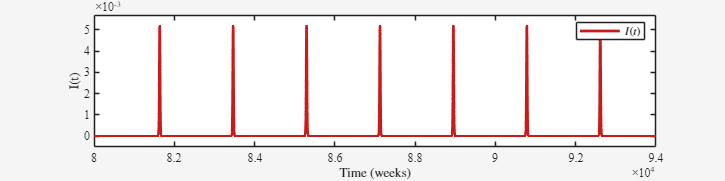

tmin = 80000;
I_plot_data = I_time_series(tmin:end);
t_plot_data = tspan(tmin:end);

fig = figure("Position", [0 0 800 200]);
axis = axes(fig);
plot(t_plot_data, I_plot_data, "DisplayName", "$I(t)$", "Color", [0.8 0.1 0.1], "LineWidth", 2);
xlabel("Time (weeks)", "Interpreter", "latex");
ylabel("I(t)", "Interpreter", "latex")
legend("Interpreter", "latex");
box(axis, "on");
%axis.XAxis.TickLength = [0 0];
axis.XAxis.FontName = "Times New Roman";
%axis.YAxis.TickLength = [0 0];
axis.YAxis.FontName = "Times New Roman";

% Add axis padding
ylen = max(I_plot_data);
ypad = ylen * 0.1;
xlim([tmin, tmax]);
ylim([-ypad, ylen + ypad]);

theme(fig, "light");

exportgraphics(fig, "relaxation_oscillation.eps", "Resolution", 300);

function dx_dt = slow_fast_model(t, x, par_dictionary)
    xi = par_dictionary("xi");
    c = par_dictionary("c");
    beta = par_dictionary("beta");
    gamma = par_dictionary("gamma");
    epsilon = par_dictionary("epsilon");
    alpha_i = par_dictionary("alpha_i");
    alpha_s = par_dictionary("alpha_s");

    Sp = x(1);
    I = x(2);
    Ss = x(3);

    dSp_dt = c*xi - beta*Sp*I - xi*Sp;
    dI_dt = beta*Sp*I + epsilon*beta*Ss*I - (gamma + xi + alpha_i)*I;
    dSs_dt = gamma*I - epsilon*beta*Ss*I - (xi + alpha_s)*Ss;

    dx_dt = [dSp_dt; dI_dt; dSs_dt];
end